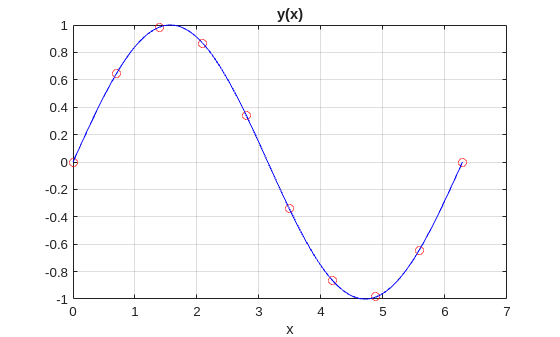

% interp_intro.m
% Wprowadzenie do zagadnienia interpolacji
clear all; close all;

% Funkcja interpolowana wielomianem i jej parametry
N = 10;                     % liczba znanych punktow funkcji, u nas sinus()
xmax = 2*pi;                % maksymalna wartosc argumentu funkcji
%xmax = 5*2*pi;                % maksymalna wartosc argumentu funkcji
xp = 0 : xmax/(N-1) : xmax; % wartosci argumentow dla znanych wartosci funkcji 
xd = 0 : 0.001 : xmax;      % wartosci argumentow w punktach interpolacji
yp = sin( xp );             % znane wartosci
yd = sin( xd );             % wartosci w punktach interpolacji - do sprawdzenia 
figure;
plot( xp, yp, 'ro', xd, yd, 'b-'); xlabel('x'); title('y(x)'); grid; 


% Wspolczynniki wielomianu y(x) = a0 + a1*x^1 + a2*x^2 + ... + aP*x^P
P = N-1; % rzad wielomianu: 0 (a0), 1 (a0 + a1*x), 2 (a0 + a1*x + a2*x^2), ...
a = polyfit( xp, yp, P ),   % obliczenie wsp. wielomianu interpolujacego

a =    -0.0000    0.0001   -0.0006    0.0017    0.0040    0.0071   -0.1738    0.0040    0.9991    0.0000



% Interpolacja funkcji w zadanych punktach xi
xi = xd;                    % argumenty punktow interpolacji
yi = polyval(a,xi);         % wartosci w punktach interpolacji
a = a(end:-1:1),            % w Matlabie wsp. sa zapisywane od najwyzszej potegi

a =     0.0000    0.9991    0.0040   -0.1738    0.0071    0.0040    0.0017   -0.0006    0.0001   -0.0000


yi_moje = zeros(1,length(xi));
for k = 1 : N              % sami obliczamy wartosci w punktach interpolacji 
    yi_moje = yi_moje + a(k) * xi.^(k-1);   
end 
max_abs_err = max( abs( yi - yi_moje) )

max_abs_err = 6.9625e-14

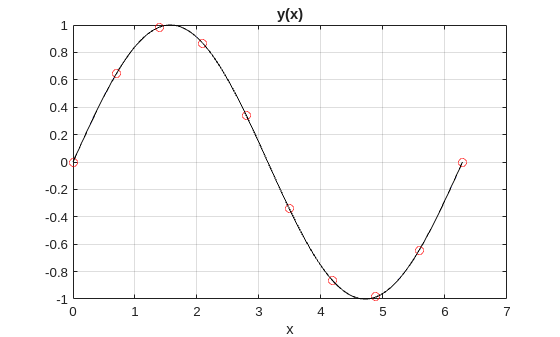


figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-' ); xlabel('x'); title('y(x)'); grid; 

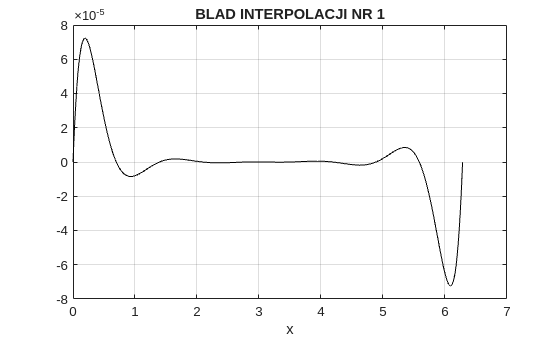

figure;
plot( xd, yd-yi, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 1'); grid; 

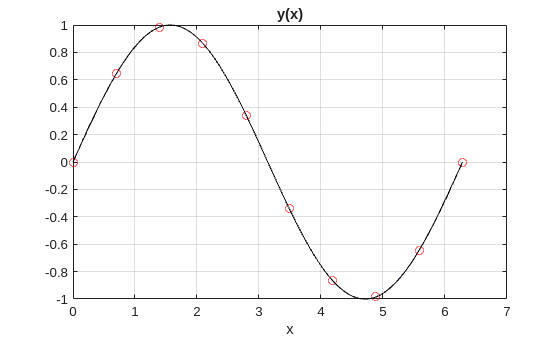


% Funkcja interpolacji w Matlabie - interp1()
% 'linear'   - (default) linear interpolation
% 'nearest'  - nearest neighbor interpolation
% 'next'     - next neighbor interpolation
% 'previous' - previous neighbor interpolation
% 'spline'   - piecewise cubic spline interpolation (SPLINE)
% 'pchip'    - shape-preserving piecewise cubic interpolation
% 'cubic'    - cubic convolution interpolation for uniformly-spaced
yis = interp1( xp, yp, xi, 'spline' );
figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-', xi,yis,'k--' );
xlabel('x'); title('y(x)'); grid; 

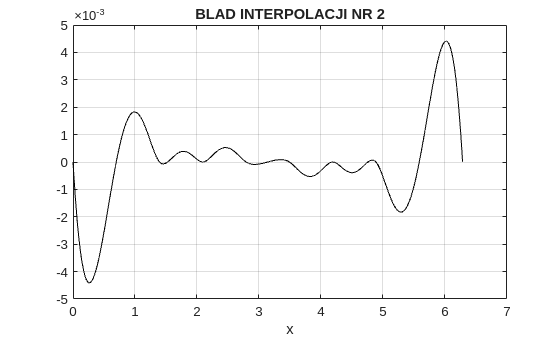

figure;
plot( xd, yd - yis, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 2'); grid; 

y = pi/4

disp("============================")

disp("y = pi/4")

y = pi/4


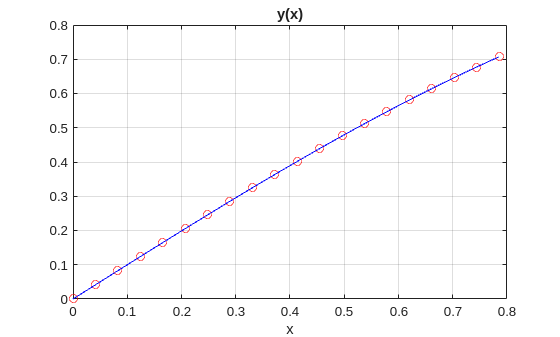

% interp_intro.m
% Wprowadzenie do zagadnienia interpolacji
clear all;

% Funkcja interpolowana wielomianem i jej parametry
N = 20;                     % liczba znanych punktow funkcji, u nas sinus()
xmax = pi/4;                % maksymalna wartosc argumentu funkcji
xp = 0 : xmax/(N-1) : xmax; % wartosci argumentow dla znanych wartosci funkcji 
xd = 0 : 0.001 : xmax;      % wartosci argumentow w punktach interpolacji
yp = sin( xp );             % znane wartosci
yd = sin( xd );             % wartosci w punktach interpolacji - do sprawdzenia 
figure;
plot( xp, yp, 'ro', xd, yd, 'b-'); xlabel('x'); title('y(x)'); grid; 


% Wspolczynniki wielomianu y(x) = a0 + a1*x^1 + a2*x^2 + ... + aP*x^P
P = N-1; % rzad wielomianu: 0 (a0), 1 (a0 + a1*x), 2 (a0 + a1*x + a2*x^2), ...
a = polyfit( xp, yp, P ),   % obliczenie wsp. wielomianu interpolujacego

a =    -0.0036    0.0270   -0.0935    0.1993   -0.2929    0.3144   -0.2553    0.1600   -0.0784    0.0301   -0.0091    0.0021   -0.0006    0.0001    0.0083    0.0000   -0.1667    0.0000    1.0000    0.0000



% Interpolacja funkcji w zadanych punktach xi
xi = xd;                    % argumenty punktow interpolacji
yi = polyval(a,xi);         % wartosci w punktach interpolacji
a = a(end:-1:1),            % w Matlabie wsp. sa zapisywane od najwyzszej potegi

a =     0.0000    1.0000    0.0000   -0.1667    0.0000    0.0083    0.0001   -0.0006    0.0021   -0.0091    0.0301   -0.0784    0.1600   -0.2553    0.3144   -0.2929    0.1993   -0.0935    0.0270   -0.0036


yi_moje = zeros(1,length(xi));
for k = 1 : N              % sami obliczamy wartosci w punktach interpolacji 
    yi_moje = yi_moje + a(k) * xi.^(k-1);   
end 
max_abs_err = max( abs( yi - yi_moje) ), 

max_abs_err = 5.5511e-16

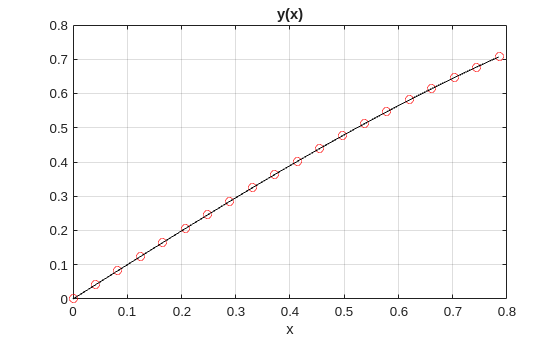


figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-' ); xlabel('x'); title('y(x)'); grid; 

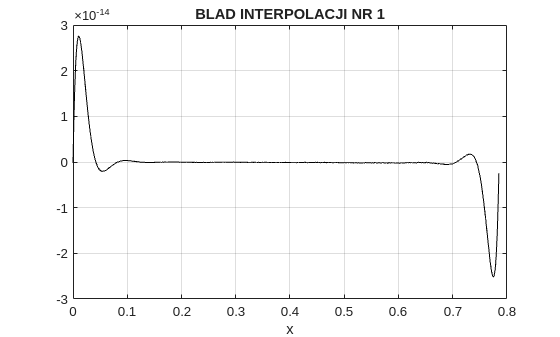

figure;
plot( xd, yd-yi, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 1'); grid; 


% Funkcja interpolacji w Matlabie - interp1()
% 'linear'   - (default) linear interpolation
% 'nearest'  - nearest neighbor interpolation
% 'next'     - next neighbor interpolation
% 'previous' - previous neighbor interpolation
% 'spline'   - piecewise cubic spline interpolation (SPLINE)
% 'pchip'    - shape-preserving piecewise cubic interpolation
% 'cubic'    - cubic convolution interpolation for uniformly-spaced
yis = interp1( xp, yp, xi, 'spline' );
figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-', xi,yis,'k--' );
xlabel('x'); title('y(x)'); grid; 

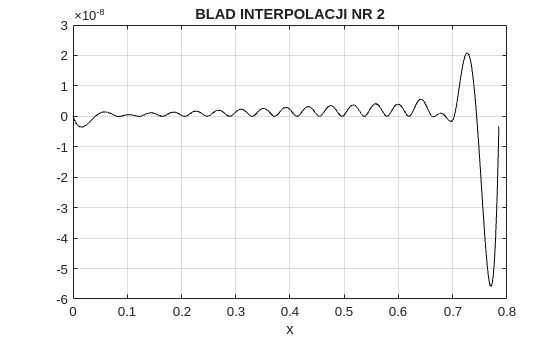

figure;
plot( xd, yd - yis, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 2'); grid; 

y = 5*2pi

disp("============================")

disp("y = 5*2pi")

y = 5*2pi


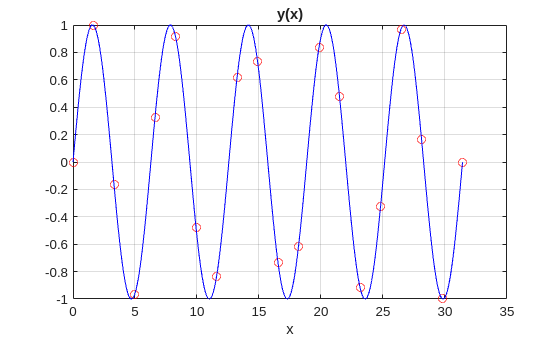

% interp_intro.m
% Wprowadzenie do zagadnienia interpolacji
clear all;

% Funkcja interpolowana wielomianem i jej parametry
N = 20;                     % liczba znanych punktow funkcji, u nas sinus()
xmax = 5*2*pi;                % maksymalna wartosc argumentu funkcji
xp = 0 : xmax/(N-1) : xmax; % wartosci argumentow dla znanych wartosci funkcji 
xd = 0 : 0.001 : xmax;      % wartosci argumentow w punktach interpolacji
yp = sin( xp );             % znane wartosci
yd = sin( xd );             % wartosci w punktach interpolacji - do sprawdzenia 
figure;
plot( xp, yp, 'ro', xd, yd, 'b-'); xlabel('x'); title('y(x)'); grid; 


% Wspolczynniki wielomianu y(x) = a0 + a1*x^1 + a2*x^2 + ... + aP*x^P
P = N-1; % rzad wielomianu: 0 (a0), 1 (a0 + a1*x), 2 (a0 + a1*x + a2*x^2), ...
a = polyfit( xp, yp, P ),   % obliczenie wsp. wielomianu interpolujacego

a =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0015    0.0173   -0.1530    1.0406   -5.3793   20.5956  -56.0350  101.3056 -108.0701   51.2357    0.0003



% Interpolacja funkcji w zadanych punktach xi
xi = xd;                    % argumenty punktow interpolacji
yi = polyval(a,xi);         % wartosci w punktach interpolacji
a = a(end:-1:1),            % w Matlabie wsp. sa zapisywane od najwyzszej potegi

a =     0.0003   51.2357 -108.0701  101.3056  -56.0350   20.5956   -5.3793    1.0406   -0.1530    0.0173   -0.0015    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000


yi_moje = zeros(1,length(xi));
for k = 1 : N              % sami obliczamy wartosci w punktach interpolacji 
    yi_moje = yi_moje + a(k) * xi.^(k-1);   
end 
max_abs_yi = max( abs( yi - yi_moje) ), 

max_abs_yi = 0.0032

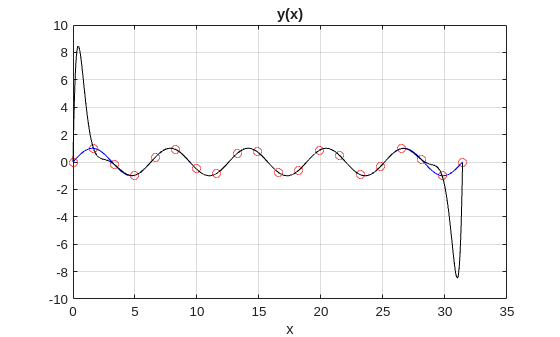


figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-' ); xlabel('x'); title('y(x)'); grid; 

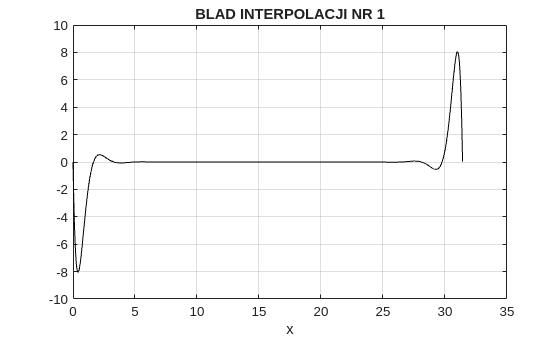

figure;
plot( xd, yd-yi, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 1'); grid; 

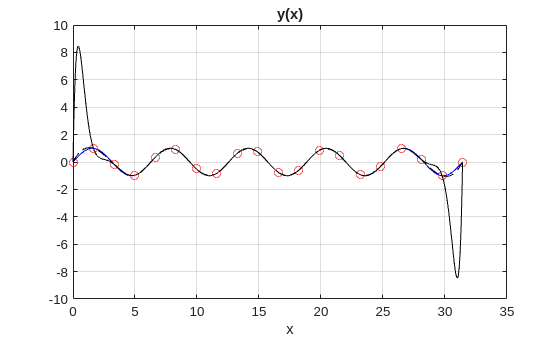


% Funkcja interpolacji w Matlabie - interp1()
% 'linear'   - (default) linear interpolation
% 'nearest'  - nearest neighbor interpolation
% 'next'     - next neighbor interpolation
% 'previous' - previous neighbor interpolation
% 'spline'   - piecewise cubic spline interpolation (SPLINE)
% 'pchip'    - shape-preserving piecewise cubic interpolation
% 'cubic'    - cubic convolution interpolation for uniformly-spaced
yis = interp1( xp, yp, xi, 'spline' );
figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-', xi,yis,'k--' );
xlabel('x'); title('y(x)'); grid; 

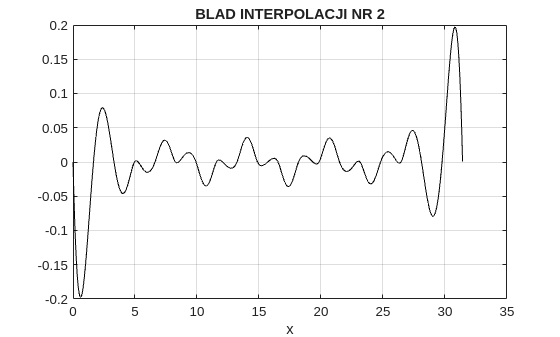

figure;
plot( xd, yd - yis, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 2'); grid; 

y = log10(x)

disp("============================")

disp("y = log10(x)")

y = log10(x)


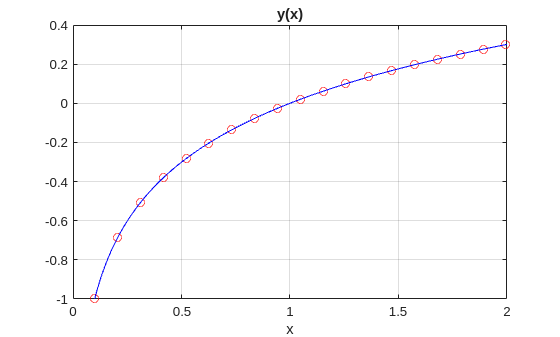

% interp_intro.m
% Wprowadzenie do zagadnienia interpolacji
clear all;

% Funkcja interpolowana wielomianem i jej parametry
N = 20; % liczba znanych punktow funkcji, u nas sinus()
xmin = 0.1;
xmax = 2;                % maksymalna wartosc argumentu funkcji
xp = xmin : xmax/(N-1) : xmax; % wartosci argumentow dla znanych wartosci funkcji 
xd = xmin : 0.001 : xmax;      % wartosci argumentow w punktach interpolacji
yp = log10( xp );             % znane wartosci
yd = log10( xd );             % wartosci w punktach interpolacji - do sprawdzenia 
figure;
plot( xp, yp, 'ro', xd, yd, 'b-'); xlabel('x'); title('y(x)'); grid; 


% Wspolczynniki wielomianu y(x) = a0 + a1*x^1 + a2*x^2 + ... + aP*x^P
P = N-1; % rzad wielomianu: 0 (a0), 1 (a0 + a1*x), 2 (a0 + a1*x + a2*x^2), ...
a = polyfit( xp, yp, P ),   % obliczenie wsp. wielomianu interpolujacego

a = 1.0e+04 *

   -0.0000    0.0009   -0.0082    0.0431   -0.1538    0.3894   -0.7080    0.8967   -0.6770         0    0.7986   -1.2533    1.1840   -0.7927    0.3925   -0.1451    0.0398   -0.0081    0.0013   -0.0002



% Interpolacja funkcji w zadanych punktach xi
xi = xd;                    % argumenty punktow interpolacji
yi = polyval(a,xi);         % wartosci w punktach interpolacji
a = a(end:-1:1),            % w Matlabie wsp. sa zapisywane od najwyzszej potegi

a = 1.0e+04 *

   -0.0002    0.0013   -0.0081    0.0398   -0.1451    0.3925   -0.7927    1.1840   -1.2533    0.7986         0   -0.6770    0.8967   -0.7080    0.3894   -0.1538    0.0431   -0.0082    0.0009   -0.0000


yi_moje = zeros(1,length(xi));
for k = 1 : N              % sami obliczamy wartosci w punktach interpolacji 
    yi_moje = yi_moje + a(k) * xi.^(k-1);   
end 
max_abs_yi = max( abs( yi - yi_moje) ), 

max_abs_yi = 1.6302e-08

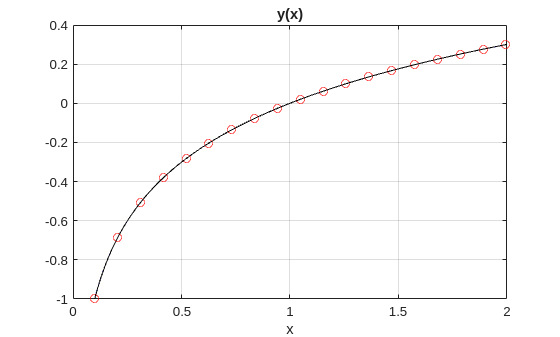


figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-' ); xlabel('x'); title('y(x)'); grid; 

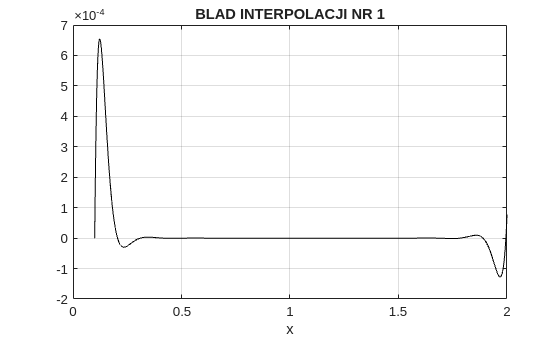

figure;
plot( xd, yd-yi, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 1'); grid; 

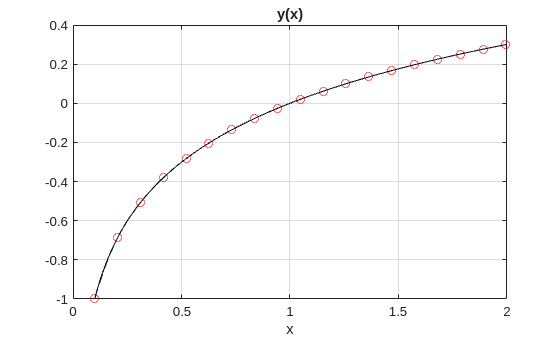


% Funkcja interpolacji w Matlabie - interp1()
% 'linear'   - (default) linear interpolation
% 'nearest'  - nearest neighbor interpolation
% 'next'     - next neighbor interpolation
% 'previous' - previous neighbor interpolation
% 'spline'   - piecewise cubic spline interpolation (SPLINE)
% 'pchip'    - shape-preserving piecewise cubic interpolation
% 'cubic'    - cubic convolution interpolation for uniformly-spaced
yis = interp1( xp, yp, xi, 'spline' );
figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-', xi,yis,'k--' );
xlabel('x'); title('y(x)'); grid; 

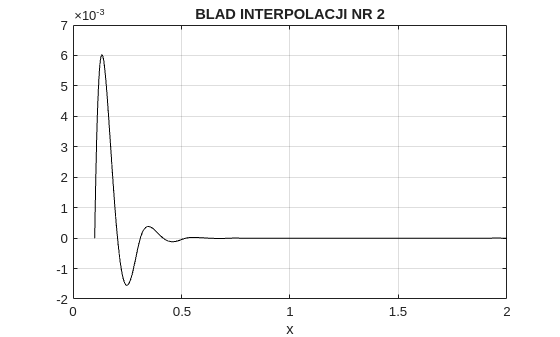

figure;
plot( xd, yd - yis, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 2'); grid; 

y = exp(x)

disp("============================")

disp("y = exp(x)")

y = exp(x)


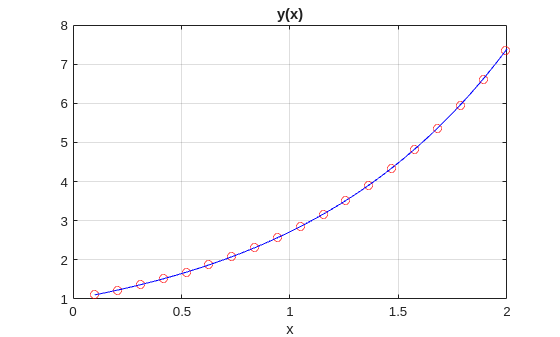

% interp_intro.m
% Wprowadzenie do zagadnienia interpolacji
clear all;

% Funkcja interpolowana wielomianem i jej parametry
N = 20; % liczba znanych punktow funkcji, u nas sinus()
xmin = 0.1;
xmax = 2;                % maksymalna wartosc argumentu funkcji
xp = xmin : xmax/(N-1) : xmax; % wartosci argumentow dla znanych wartosci funkcji 
xd = xmin : 0.001 : xmax;      % wartosci argumentow w punktach interpolacji
yp = exp( xp );             % znane wartosci
yd = exp( xd );             % wartosci w punktach interpolacji - do sprawdzenia 
figure;
plot( xp, yp, 'ro', xd, yd, 'b-'); xlabel('x'); title('y(x)'); grid; 


% Wspolczynniki wielomianu y(x) = a0 + a1*x^1 + a2*x^2 + ... + aP*x^P
P = N-1; % rzad wielomianu: 0 (a0), 1 (a0 + a1*x), 2 (a0 + a1*x + a2*x^2), ...
a = polyfit( xp, yp, P ),   % obliczenie wsp. wielomianu interpolujacego

a =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0002    0.0014    0.0083    0.0417    0.1667    0.5000    1.0000    1.0000



% Interpolacja funkcji w zadanych punktach xi
xi = xd;                    % argumenty punktow interpolacji
yi = polyval(a,xi);         % wartosci w punktach interpolacji
a = a(end:-1:1),            % w Matlabie wsp. sa zapisywane od najwyzszej potegi

a =     1.0000    1.0000    0.5000    0.1667    0.0417    0.0083    0.0014    0.0002    0.0000   -0.0000         0    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000


yi_moje = zeros(1,length(xi));
for k = 1 : N              % sami obliczamy wartosci w punktach interpolacji 
    yi_moje = yi_moje + a(k) * xi.^(k-1);   
end 
max_abs_yi = max( abs( yi - yi_moje) ), 

max_abs_yi = 3.5527e-15

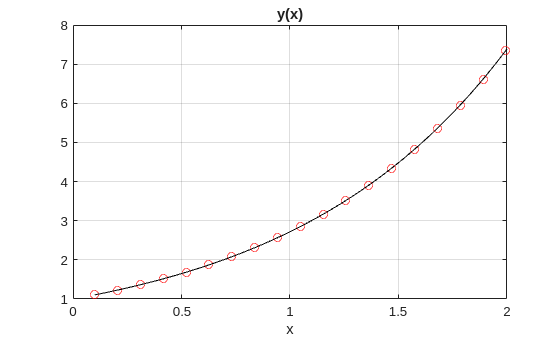


figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-' ); xlabel('x'); title('y(x)'); grid; 

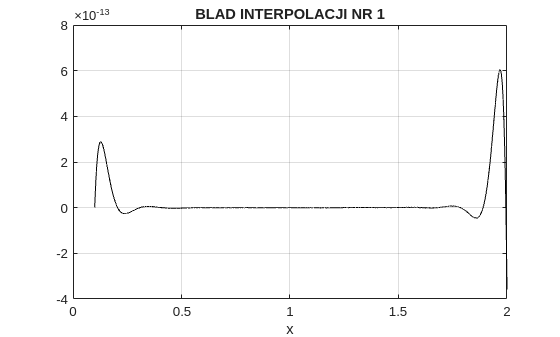

figure;
plot( xd, yd-yi, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 1'); grid; 


% Funkcja interpolacji w Matlabie - interp1()
% 'linear'   - (default) linear interpolation
% 'nearest'  - nearest neighbor interpolation
% 'next'     - next neighbor interpolation
% 'previous' - previous neighbor interpolation
% 'spline'   - piecewise cubic spline interpolation (SPLINE)
% 'pchip'    - shape-preserving piecewise cubic interpolation
% 'cubic'    - cubic convolution interpolation for uniformly-spaced
yis = interp1( xp, yp, xi, 'spline' );
figure;
plot( xp,yp,'ro', xd,yd,'b-', xi,yi,'k-', xi,yis,'k--' );
xlabel('x'); title('y(x)'); grid; 

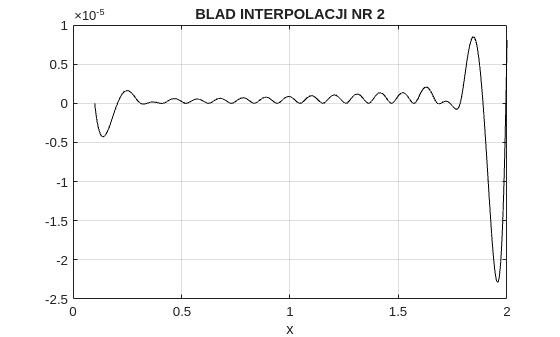

figure;
plot( xd, yd - yis, 'k-' ); xlabel('x'); title('BLAD INTERPOLACJI NR 2'); grid; 